# Übung 3

## 3.01 Vorbereitung

Stellen Sie durch zwei geeignete Matlab-Befehle sicher, dass

- der Workspace initialisiert ist,

- alle Figures (Diagrammfenster) geschlossen sind und

- die Darstellung der Ergebnisse 'compact', also ohne zusätzliche Leerzeilen erfolgt.

close all
clear all
format compact
clc

Im Folgenden ergänzen/erweitern Sie dieses Script. Sofern nicht anders angegeben, unterdrücken Sie die Ergebnisausgabe (Strichpunkt am Zeilenende). Wenn Sie alle Übungsaufgaben bearbeitet haben, publizieren ('publishen') Sie das Skript als PDF. Geben Sie dieses PDF (und nur dieses PDF) zur Kontrolle ab (moodle/Laufwerk/email).

## 3.02 Messdaten

An bis zu vier Drahtstücken, in Reihen- und Parallelschaltung, wird eine Spannung von 1 V angelegt und der dann fließende Strom gemessen. Die Länge der Drahtstücke ist 1 m, der Durchmesser beträgt 0.4 mm.

%figure
%img = imread('Ue3.png');
%imshow(img);
%title('Messschaltungen');

% Messspannung
U = 1; %V

% Drahtgeometrie
l = 1; %m
d = 0.4; %mm

% Messtabelle
%               N*R/R   I/mA    Bemerkung
Messung =  [    
    4       60      % 4 Stücke in Reihe
    3       80      % 3 Stücke in Reihe
    2       117     % 2 Stücke in Reihe
    1       220     % 1 Stück
    1/2     385     % 2 Stücke parallel
    1/3     516     % 3 Stücke parallel
    1/4     618 ]   % 4 Stücke parallel

Messung =     4.0000   60.0000
    3.0000   80.0000
    2.0000  117.0000
    1.0000  220.0000
    0.5000  385.0000
    0.3333  516.0000
    0.2500  618.0000


## 3.03 Datenextraktion

Extrahieren Sie die Daten der Messtabelle in zwei Vektoren *N* und *Imess*.

N = Messung(:, 1)

N =     4.0000
    3.0000
    2.0000
    1.0000
    0.5000
    0.3333
    0.2500


lmess = Messung(:, 2)

lmess =     60
    80
   117
   220
   385
   516
   618


## 3.04 Plot der Daten

Plotten Sie die Ströme über dem Widerstandsfaktor N, ohne die einzelnen Datenpunkte durch Linien zu verbinden. Beschriften Sie das Diagramm aussagekräftig.

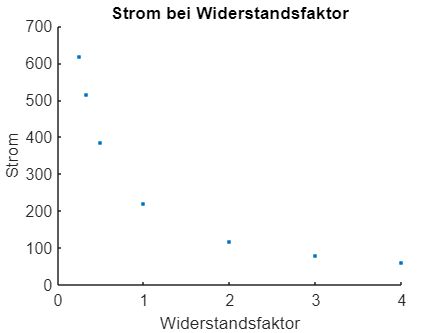

figure
newplot()

hold on

myPlot(N, lmess, 'Strom bei Widerstandsfaktor', 'Widerstandsfaktor', 'Strom')

hold off

## 3.05 Widerstandsberechnung

Berechnen Sie aus der angelegten Spannung und den gemessenen Stromstärken die Gesamtwiderstände *Rgem* der Schaltungen in Ohm.

Rgem = U ./ lmess*1000; %Ohm

## 3.06 Teilwiderstand

Berechnen Sie den Teilwiderstand der Drahtstücke durch Division der Gesamtwiderstände durch N. Berechnen Sie den Mittelwert (*R*) und die zweifache Standardabweichung (*dR*).

Rteil = Rgem ./ N

Rteil =     4.1667
    4.1667
    4.2735
    4.5455
    5.1948
    5.8140
    6.4725


## 3.07 Ergebnis

Geben Sie den Mittelwert *R* und die zweifache Standardabweichung *dR* als Endergebnis an. Runden Sie hierzu zunächst *dR* auf zwei signifikante Stellen und runden Sie dann *R* auf die selbe Zahl von Nachkommastellen wie *dR*. Verwenden Sie für *R* und *dR* den selben Exponenten!

MeanR = mean(Rteil)

MeanR = 4.9476

zweifache_standardabweichung = 2 * std(Rteil)

zweifache_standardabweichung = 1.8208

Geben Sie das Endergebnis auch als Mittelwert mit relativem Fehler (in Prozent, ohne Nachkommastellen) an.

fprintf( 'R = (%.1f +- %.1f) Ohm\n', MeanR, zweifache_standardabweichung );

R = (4.9 +- 1.8) Ohm


fprintf( 'R = %.1f Ohm +- %.f %%\n', MeanR, zweifache_standardabweichung/MeanR*100 );

R = 4.9 Ohm +- 37 %


## 3.08 Alternative Auswertung

Plotten Sie die Gesamtwiderstände aus Aufgabe 3.05 über dem Widerstandsfaktor *N*, ohne die einzelnen Datenpunkte zu verbinden.

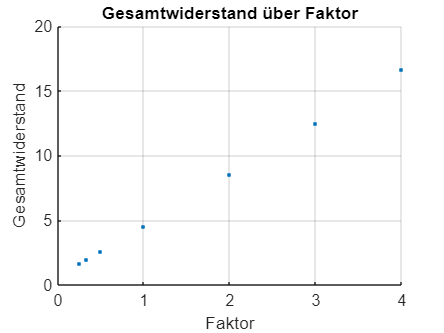

figure
newplot()
grid on

hold on

myPlot(N, Rgem, 'Gesamtwiderstand über Faktor', 'Faktor', 'Gesamtwiderstand')


%hold off

## 3.09 Kurvenanpassung

Benutzen Sie die Funktion *polyfit* um die Gesamtwiderstände mit einer Funktion erster Ordnung zu interpolieren. Lassen Sie sich von *polyfit* auch die Datenstruktur *'S'* zur späteren Fehlerabschätzung zurück geben (*help ployfit*). Geben die die Ergebnisfunktion an. Interpretieren Sie das Ergebnis (zunächst ohne Berücksichtigung der Struktur 'S').

% store the polyfit polygon result
[Rber, S] = polyfit(N, Rgem, 1)

Rber =     4.0002    0.5825


S = struct with fields:
        R: [2×2 double]
       df: 5
    normr: 0.1360

Rmean = Rber(1);
Rext = Rber(2);
fprintf('R = %3.2f Ohm * N + %3.2f Ohm\n', Rmean, Rext);

R = 4.00 Ohm * N + 0.58 Ohm


fprintf('Steigung (Drahtwiderstand je Stück): %3.2f Ohm\n', Rmean );

Steigung (Drahtwiderstand je Stück): 4.00 Ohm


fprintf('Abschnitt (Summe anderer Widerstände): %3.2f Ohm \n', Rext );

Abschnitt (Summe anderer Widerstände): 0.58 Ohm 


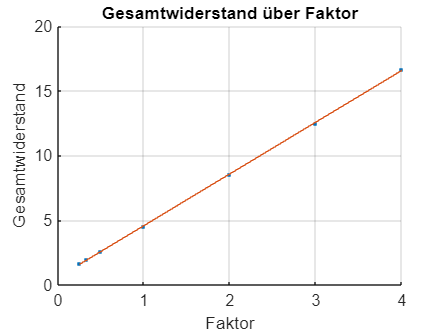


% compute the values of the polynomial at 
% specific X values for plotting
[ Rb dRb ] =  polyval(Rber, N, S);

plot(N,  Rb)


%hold off

## 3.10 Plotten der Interpolationsfunktion

Verwenden Sie die Funktion *polyval* um eine Anzahl von Widerstandswerten der Interpolationsfunktion und deren abgeschätze Fehler zu berechnen (Datenstruktur *'S'*). Stellen Sie die Funktion im vorherigen Graphen dar (*hold*, *errorbar*).

T = table(N, Rgem, Rb, (Rgem - Rb), 'VariableNames', {'X', 'Y', 'Fit', 'FitError'})

T = 7×4 table
       X         Y        Fit      FitError 
    _______    ______    ______    _________
          4    16.667    16.583      0.08353
          3      12.5    12.583     -0.08298
          2     8.547    8.5828    -0.035815
          1    4.5455    4.5827    -0.037212
        0.5    2.5974    2.5826     0.014814
    0.33333     1.938    1.9159     0.022089
       0.25    1.6181    1.5825     0.035574

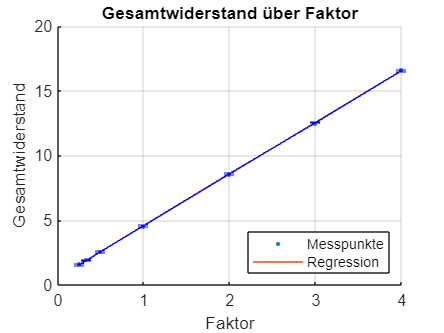



hold on
%errorbar(Rgem, Rgem-f)
errorbar( N, Rb, dRb, 'b-' );

hold off

legend( 'Messpunkte', 'Regression', 'Location', 'Southeast' );

## 3.11 Fitting-Fehlerrechnung, einfach

Bestimmen Sie aus dem ersten und dem letzen Datensatz der Kurvenanpassung die minimal und maximal mögliche Steigung der Interpolationsfunktion. Bestimmen Sie daraus *dR*. Geben Sie die mittlere Steigung und die maximale Abweichung als Endergebnis an.

Rmax = ((Rb(end)-dRb(end))-(Rb(1)+dRb(1)))/(N(end)-N(1));
Rmin = ((Rb(end)+dRb(end))-(Rb(1)-dRb(1)))/(N(end)-N(1));
dR = max( [ (Rmax-Rmean) (Rmean-Rmin) ] );
fprintf('R = (%3.2f +- %3.2f) Ohm\n', Rmean, dR );

R = (4.00 +- 0.04) Ohm


Geben Sie das Endergebnis auch als Mittelwert mit relativem Fehler (in Prozent, ohne Nachkommastellen) an.

dR_R = dR/Rmean;
fprintf( 'R = %.1f Ohm +- %.f %%\n', Rmean, dR_R*100 );

R = 4.0 Ohm +- 1 %


## 3.12 Berechnen des spezifischen Widerstands

Berechnen Sie aus dem mittleren Drahtwiderstand den spezifischen Widerstand des verwendeten Materials und bestimmen sie das Material durch eine Internet-Recherche.

% Querschnittsfläche
A = pi*(d/2)^2;

% spez. Wid.
Rho = Rmean/l*A;
fprintf('Drahtgeometrie: Länge: %3.2f m, Querschnitt: %3.2f mm² \n', l, A );

Drahtgeometrie: Länge: 1.00 m, Querschnitt: 0.13 mm² 


fprintf('Spezifische Leitfähigkeit: %3.2f m/(Ohm mm²) \n', 1/Rho );

Spezifische Leitfähigkeit: 1.99 m/(Ohm mm²) 


fprintf('Literaturwert Konstantan: 2 m/(Ohm mm²) (wikipedia)\n');

 Literaturwert Konstantan: 2 m/(Ohm mm²) (wikipedia)


fprintf('Spezifischer Widerstand: %3.2f Ohm mm²/m \n', Rho );

Spezifischer Widerstand: 0.50 Ohm mm²/m 


function myPlot(x_data, y_data, tTitle, xLabel, yLabel)
   
    title(tTitle)
    xlabel(xLabel)
    ylabel(yLabel)
    
    %plot(x_data, y_data)
    plot(x_data, y_data, 'linestyle', 'none', 'marker', '.')
    %stairs(x_data, y_data)
    %bar(x_data, y_data)
    
end
